# การวิเคราะห์เชิงความถี่

# ตอนที่ 1 : แนวคิดของความถี่ของสัญญาณ (Concept of Frequency of Signal)

ในทางทฤษฎี **สัญญาณสามารถถูกแบ่งเป็นผลรวมของสัญญาณคลื่นไซน์ (sinusoidal) ที่มีความถี่ที่แตกต่างกัน** เพื่อให้เข้าถึงองค์ประกอบของสัญญาณโดยทั่วไป เราจะวิเคราะห์ถึงองค์ประกอบของสัญญาณคลื่นไซน์ซึ่งสัญญาณคลื่นไซน์ $y\left(t\right)$ สามารถเขียนเป็นฟังก์ชันได้ดังต่อไปนี้


$$y\left(t\right)=R\;\cos \left(2\pi \textrm{ft}+\phi \right)$$


โดยที่

$R\;\left\lbrack \textrm{unit}\right\rbrack$ คือ แอมพลิจูด (Amplitude) ของคลื่น

$f\left\lbrack \textrm{Hz}\right\rbrack$ คือ ความถี่ (frequency) ของคลื่น

$\phi \;\left\lbrack \mathrm{rad}\right\rbrack$  คือ มุมเฟส (phase angle)

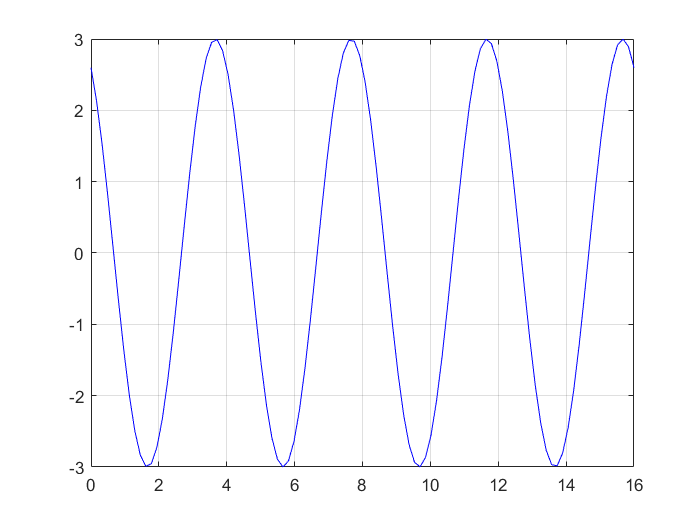

R = 3;
f = 0.25;
phi = pi/6;
t = linspace(0,4/f,100)';
y = R*cos(2*pi*f*t+phi);
ax = axes;
plot(ax,t,y,'b');
grid(ax,'on');

ในบางครั้ง การวิเคราะห์สัญญาณอาจจะใช้ตัวแปรความถี่เชิงมุม (angular frequency) $\omega \;\left\lbrack \frac{\textrm{rad}}{s}\right\rbrack$ ซึ่งมีความสัมพันธ์กับความถี่ปกติดังต่อไปนี้


$$\omega =2\pi f$$


ดังนั้นเราสามารถเขียนสัญญาณได้ดังต่อไปนี้


$$y\left(t\right)=R\;\cos \left(\omega t+\phi \right)$$


ถ้าเรามีสัญญาณที่มีความถี่เท่ากันและเอามารวมกัน เราสามารถที่จะรวมแอพลิจูดของสัญญาณนี้ได้ 

กำหนดให้ สัญญาณ A $\left(y_A \right)$ และสัญญาณ B $\left(y_B \right)$ มีแอมพลิจูดเท่ากับ $R_A$ และ $R_B$ และมุมเฟสเท่ากับ $\phi_A$ และ $\phi_B$ โดยให้ความถี่เชิงมุมเท่ากับ $\omega$ ซึ่งสามารถเขียนเป็นสมการได้ดังต่อไปนี้


$$\begin{array}{l}
y_A \left(t\right)=R_A \cos \left(\omega t+\phi_A \right)\\
y_B \left(t\right)=R_B \cos \left(\omega t+\phi_B \right)
\end{array}$$


หากเรานำทั้งสองสัญญาณนี้มารวมกัน เราจะได้สัญญาณลัพธ์ดังต่อไปนี้


$$y\left(t\right)=y_A \left(t\right)+y_B \left(t\right)=R_A \cos \left(\omega t+\phi_A \right)+R_B \cos \left(\omega t+\phi_B \right)$$


เพื่อการจัดรูป เราสามารถกระจาย $\cos$ ของผลบวกได้ดังต่อไปนี้


$$\begin{array}{l}
y\left(t\right)=R_A \cos \left(\omega t\right)\cos \left(\phi_A \right)-R_A \sin \left(\omega t\right)\sin \left(\phi_A \right)+R_B \cos \left(\omega t\right)\cos \left(\phi_B \right)-R_B \sin \left(\omega t\right)\sin \left(\phi_B \right)\\
y\left(t\right)=\left\lbrack R_A \cos \left(\phi_A \right)+R_B \cos \left(\phi_B \right)\right\rbrack \cos \left(\omega t\right)-\left\lbrack R_A \sin \left(\phi_A \right)+R_B \sin \left(\phi_B \right)\right\rbrack \sin \left(\omega t\right)
\end{array}$$


เพื่อการจัดรูป เราจะกำหนดให้


$$\begin{array}{l}
R\;\cos \left(\phi \right)=R_A \cos \left(\phi_A \right)+R_B \cos \left(\phi_B \right)\\
R\;\sin \left(\phi \right)=R_A \sin \left(\phi_A \right)+R_B \sin \left(\phi_B \right)
\end{array}$$


การกำหนดดังกล่าวทำให้เราจัดรูปสัญญาณให้เป็นรูปปกติได้ดังต่อไปนี้


$$y\left(t\right)=R\;\cos \left(\omega t+\phi \right)$$



$$\begin{array}{l}
R=\sqrt{R_A^2 +R_B^2 +2R_A R_B \left(\cos \left(\phi_A -\phi_B \right)\right)}\\
\phi =\tan^{-1} \left(\frac{R_A \sin \left(\phi_A \right)+R_B \sin \left(\phi_B \right)}{R_A \cos \left(\phi_A \right)+R_B \cos \left(\phi_B \right)}\right)
\end{array}$$


การคำนวณแสดงให้เห็นว่า**เราสามารถนำสัญญาณคลื่นไซน์ที่มีความถี่เดียวกันได้เป็นคลื่นเดียวกัน**

R_A = 3;
R_B = 5;
phi_A = pi/6;
phi_B = pi/4;
f = 0.25;
w = 2*pi*f;
t = linspace(0,4/f,100)';
y_A = R_A*cos(w*t+phi_A);
y_B = R_B*cos(w*t+phi_B);
y_C = y_A+y_B;
R = sqrt(R_A^2+R_B^2+2*R_A*R_B*cos(phi_A-phi_B));
phi = atan((R_A*sin(phi_A)+R_B*sin(phi_B))/(R_A*cos(phi_A)+R_B*cos(phi_B)));
y_D = R*cos(w*t+phi);
clf
ax = axes;
hold(ax,'on')
plot(ax,t,y_C,'b');
plot(ax,t,y_D,'ro');
grid(ax,'on');

**หากเรารวมสัญญาณคลื่นไซน์ที่มีความถี่ที่แตกต่างกัน เราจะได้ฟังก์ชันที่เป็นคาบ แต่เราจะไม่ได้ฟังก์ชันที่เป็นคลื่นไซน์** ยกตัวอย่างเช่น


$$y\left(t\right)=R_A \cos \left(\omega_A t+\phi_A \right)+R_B \cos \left(\omega_B t+\phi_B \right)$$


โดยที่


$$\begin{array}{l}
R_A >R_B \\
\omega_A <\omega_B 
\end{array}$$


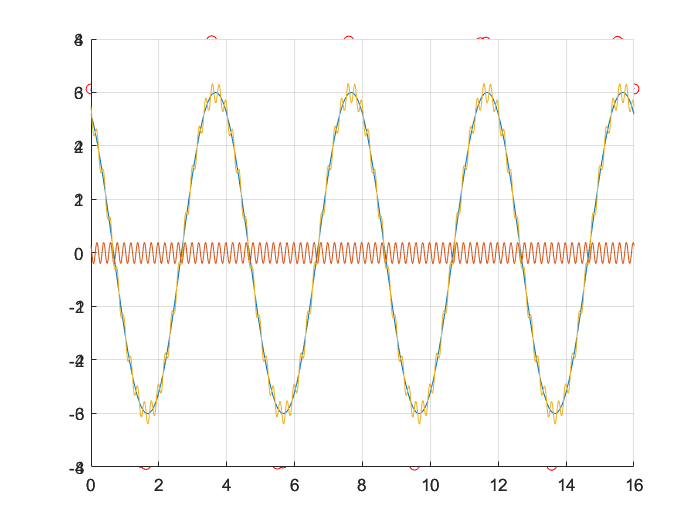

R_A = 3;
R_B = 0.2;
phi_A = pi/6;
phi_B = pi/4;
f = 0.25;
w_A = 2*pi*f;
w_B = 2*pi*f*20;
t = linspace(0,4/f,1000)';
y_A = R_A*cos(w_A*t+phi_A);
y_B = R_B*cos(w_B*t+phi_B);
y_C = y_A+y_B;
ax = axes;
hold(ax,'on')
plot(ax,t,y_A);
plot(ax,t,y_B);
plot(ax,t,y_C);
grid(ax,'on');